# Seed

clear all,
close all

%pixelpitch = 4.65; % µm - DataRay 

t1 = imread('D:\PhD\Labs\Data\20210222 Spiricon axicon seed direct/210226 seed2mm Dax120 greyscale.bmp');
% should work with tiff and bmp images - be careful with dimensions : t should be a 2D-matrix 
% only grey-level images 

size(t1) % it has to be a 1 x 2 matrix

ans =    570   776



imageData1 = medfilt2(t1); % 2nd order median filter for noise reduction - performs median filtering of the image I in two dimensions. Each output pixel contains the median value in a 3-by-3 neighborhood around the corresponding pixel in the input image.

imageData1 = im2double(imageData1); %conversion to double(double is the default numeric data type (class) in MATLAB®, providing sufficient precision for most computational tasks. Numeric variables are automatically stored as 64-bit (8-byte) double-precision floating-point values.
minlevel1 = min(imageData1(:))

minlevel1 = 0


zerolevel1 = max(max(imageData1(1:20,1:20)))%use a top-left square of 20 lines to determine the zerolevel - be careful to have noise only there

zerolevel1 = 0.0039

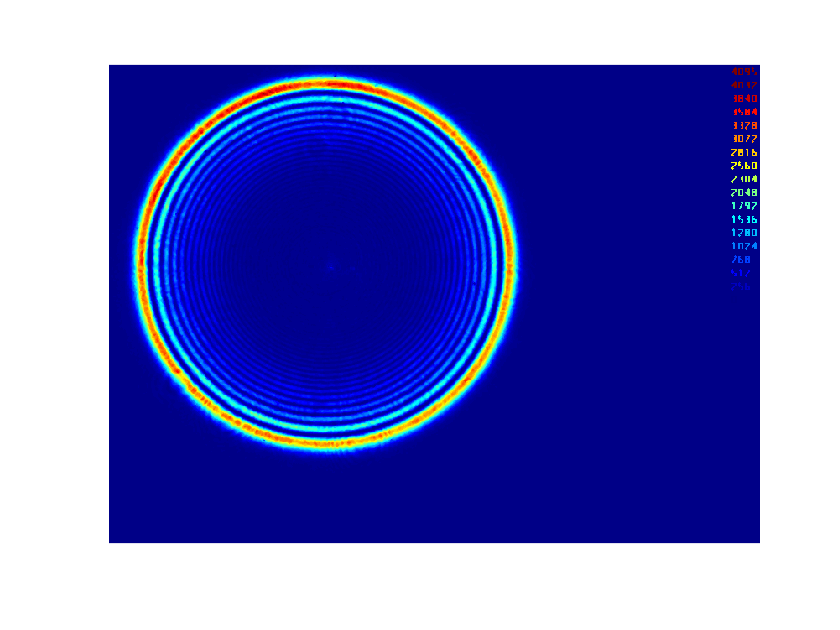

imageData1=imageData1-min(imageData1(:));

figure(1)
imagesc(imageData1)
colormap jet, axis equal, axis off



I_seed = interp2((interp2((imageData1))));
%Vq = interp2(V) returns the interpolated values on a refined grid formed by dividing the interval between sample values once in each dimension.
%==> linear interpolation on a grid which pitch is 4 times smaller than the
%initial image - dimension = 4*N - 3
Isize_seed = size(I_seed)

Isize_seed =         2277        3101



x1 = linspace(1,Isize_seed(2),Isize_seed(2));%Isize(2) = 3069 at the second column of Isize,y = linspace(x1,x2,n) generates n points between x1 and x2. The spacing between the points is (x2-x1)/(n-1).
y1 = linspace(1,Isize_seed(1),Isize_seed(1));%Isize(1) = 3069 at the first column of Isize,
[X1,Y1]=meshgrid(x1,y1);



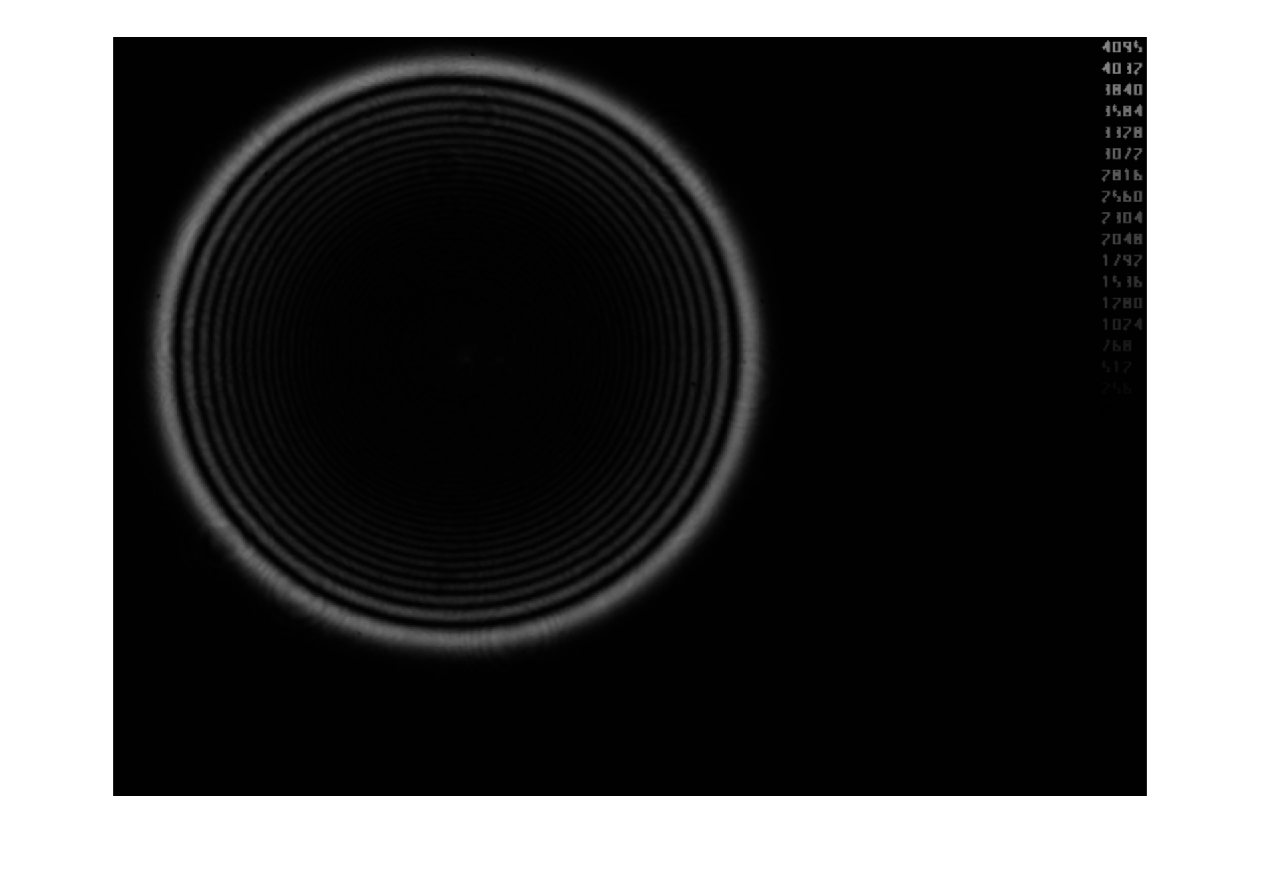

[Icrop1, rect1] = imcrop(I_seed); % crop image with user feedback 



close
% J = imcrop(I) displays the image I in a figure window and creates an interactive Crop Image tool associated with the image.
% Perform the crop operation by double-clicking in the crop rectangle or selecting Crop Image on the context menu.

X_crop1 = imcrop(X1,rect1); Y_crop1 = imcrop(Y1,rect1); %crop coordinates identically

%[c,index]=max(Icrop(:)); % for BMP images only;find the maximum value of the image in the cropped zone and its index 

Icrop1=Icrop1-1.00*zerolevel1; % for tiff images;remove the zero level from the data 
Icrop1(Icrop1<0)=0;% for tiff images;every negative value will be zero - if ever some data were below zerolevel

dimIcrop1 = size(Icrop1);

[c1,index1]=max(Icrop1(:))% for tiff images;find the maximum, c--maximum, index--its index in x and y axes

c1 = 0.4863

index1 = 1321930

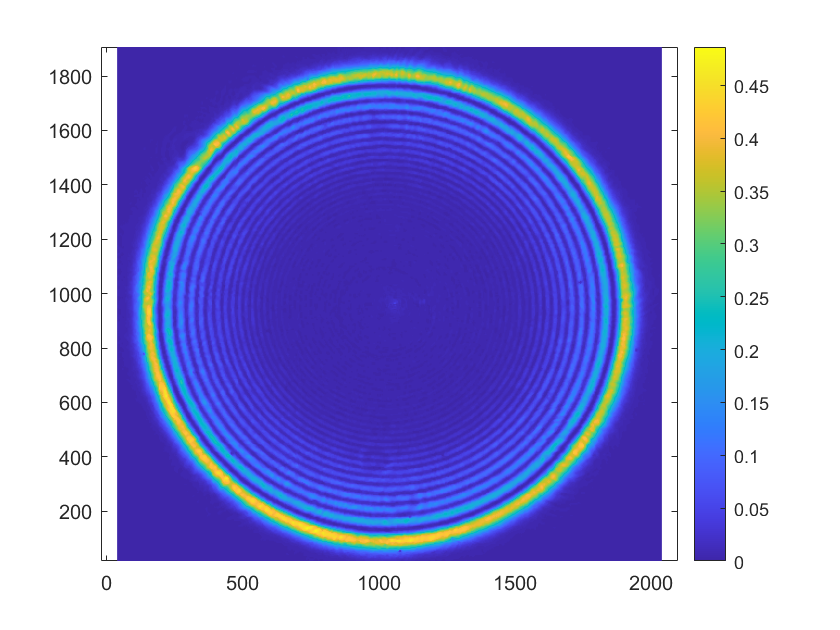




%figure, imagesc(Icrop)
figure,pcolor(X_crop1,Y_crop1,Icrop1);shading interp;colorbar;axis equal;

# TA

t2 = imread('D:\PhD\Labs\Data\20210222 Spiricon axicon seed direct/210304 beam 3mm Tz2 grey.bmp');
% should work with tiff and bmp images - be careful with dimensions : t should be a 2D-matrix 
% only grey-level images 

size(t2) % it has to be a 1 x 2 matrix

ans =    570   776



imageData2 = medfilt2(t2); % 2nd order median filter for noise reduction - performs median filtering of the image I in two dimensions. Each output pixel contains the median value in a 3-by-3 neighborhood around the corresponding pixel in the input image.

imageData2 = im2double(imageData2); %conversion to double(double is the default numeric data type (class) in MATLAB®, providing sufficient precision for most computational tasks. Numeric variables are automatically stored as 64-bit (8-byte) double-precision floating-point values.
minlevel2 = min(imageData2(:))

minlevel2 = 0


zerolevel2 = max(max(imageData2(1:20,1:20)))%use a top-left square of 20 lines to determine the zerolevel - be careful to have noise only there

zerolevel2 = 0.0078

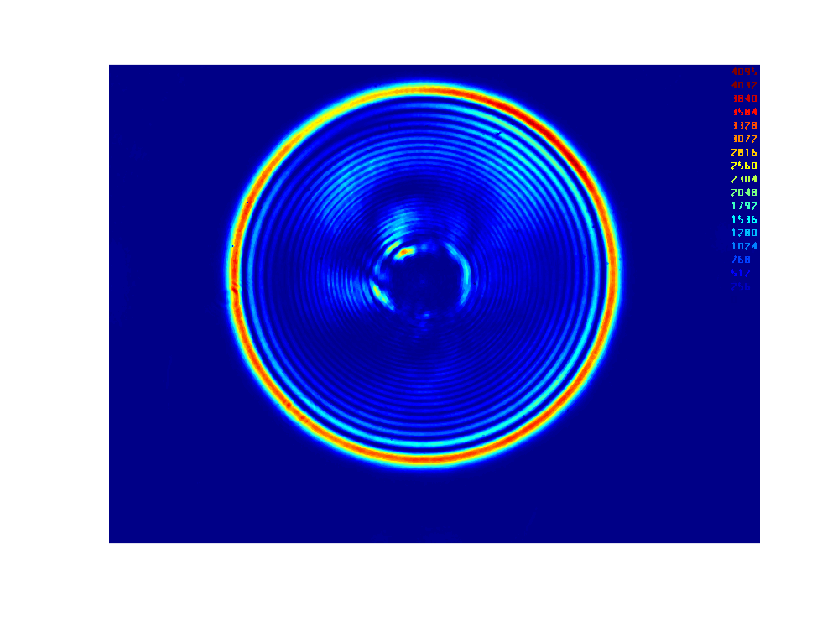


imageData2=imageData2-min(imageData2(:));

figure(2)
imagesc(imageData2)
colormap jet, axis equal, axis off



I_TA = interp2((interp2((imageData2))));
%Vq = interp2(V) returns the interpolated values on a refined grid formed by dividing the interval between sample values once in each dimension.
%==> linear interpolation on a grid which pitch is 4 times smaller than the
%initial image - dimension = 4*N - 3
Isize_TA = size(I_TA)

Isize_TA =         2277        3101



x2 = linspace(1,Isize_TA(2),Isize_TA(2));%Isize(2) = 3069 at the second column of Isize,y = linspace(x1,x2,n) generates n points between x1 and x2. The spacing between the points is (x2-x1)/(n-1).
y2 = linspace(1,Isize_TA(1),Isize_TA(1));%Isize(1) = 3069 at the first column of Isize,
[X2,Y2]=meshgrid(x2,y2);

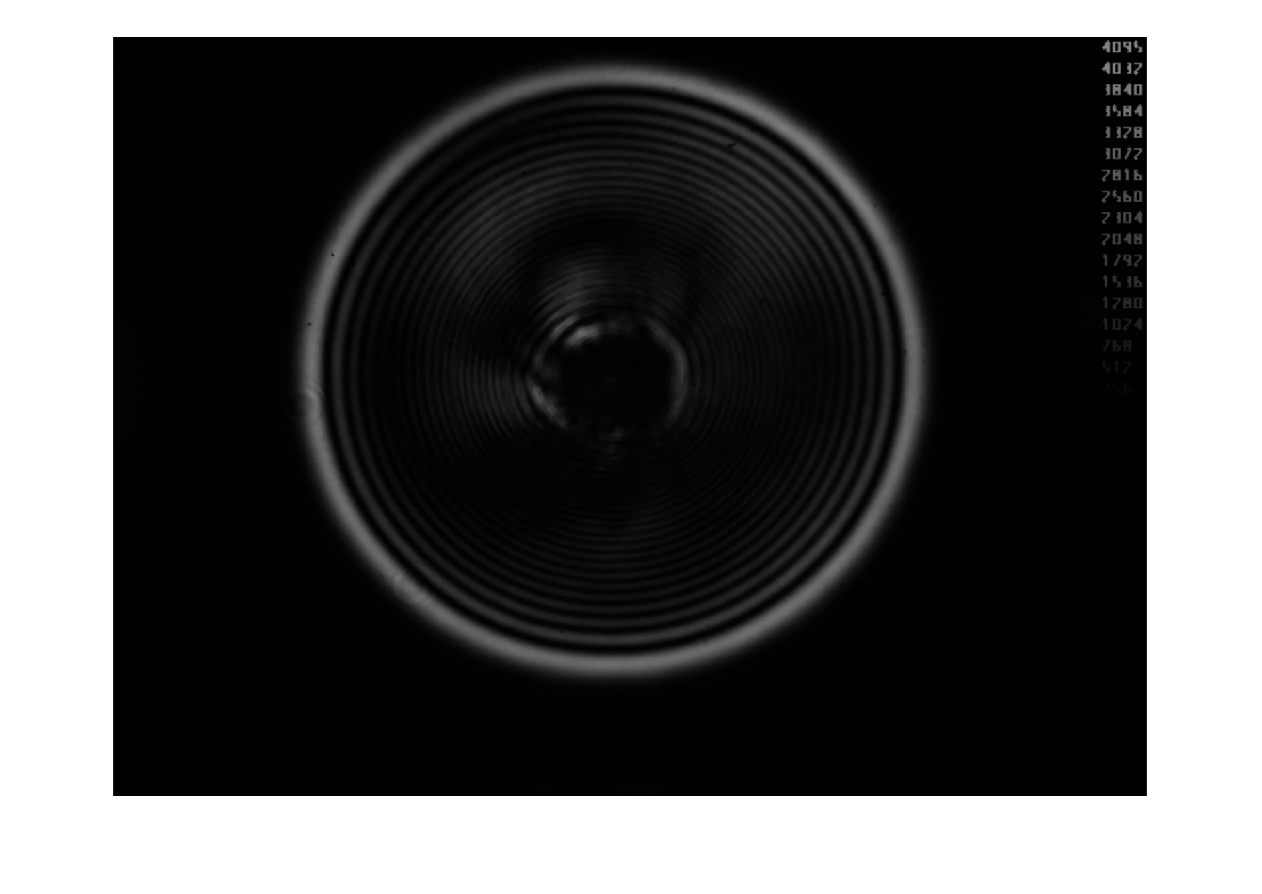

[Icrop2, rect2] = imcrop(I_TA); % crop image with user feedback 


close
% J = imcrop(I) displays the image I in a figure window and creates an interactive Crop Image tool associated with the image.
% Perform the crop operation by double-clicking in the crop rectangle or selecting Crop Image on the context menu.

X_crop2 = imcrop(X2,rect2); Y_crop2 = imcrop(Y2,rect2); %crop coordinates identically

%[c,index]=max(Icrop(:)); % for BMP images only;find the maximum value of the image in the cropped zone and its index 

Icrop2=Icrop2-1.00*zerolevel2; % for tiff images;remove the zero level from the data 
Icrop2(Icrop2<0)=0;% for tiff images;every negative value will be zero - if ever some data were below zerolevel

dimIcrop2 = size(Icrop2);

[c2,index2]=max(Icrop2(:))% for tiff images;find the maximum, c--maximum, index--its index in x and y axes

c2 = 0.4784

index2 = 3420527

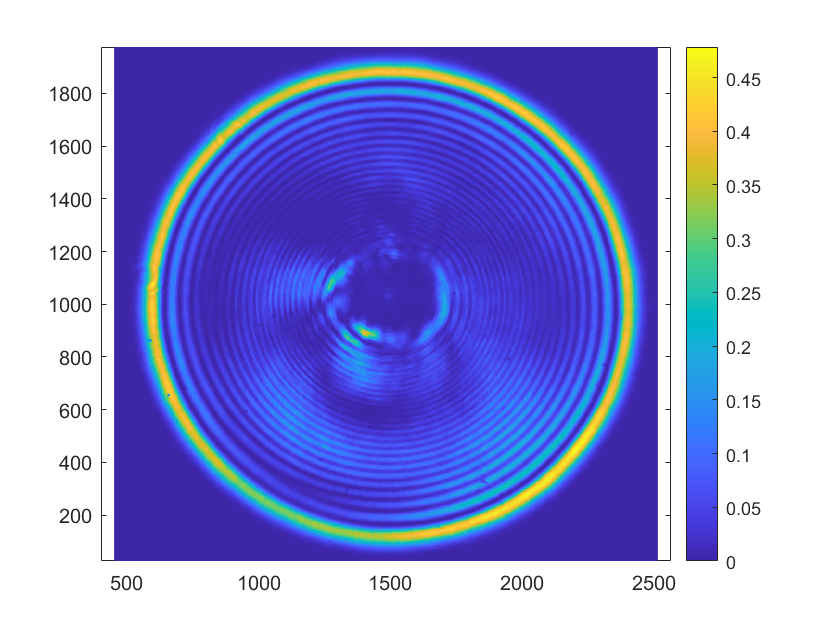



%figure, imagesc(Icrop)
figure,pcolor(X_crop2,Y_crop2,Icrop2);shading interp;colorbar;axis equal;

xaxis = (-954:951)

xaxis =   -954  -953  -952  -951  -950  -949  -948  -947  -946  -945  -944  -943  -942  -941  -940  -939  -938  -937  -936  -935  -934  -933  -932  -931  -930  -929  -928  -927  -926  -925  -924  -923  -922  -921  -920  -919  -918  -917  -916  -915  -914  -913  -912  -911  -910  -909  -908  -907  -906  -905


Icrop222 = Icrop1(:,1000)

Icrop222 =     0.0118
    0.0127
    0.0137
    0.0147
    0.0157
    0.0186
    0.0216
    0.0245
    0.0275
    0.0304


plot(xaxis, Icrop1(:,1000),'r','LineWidth',1)

Error using plot
Vectors must be the same length.

hold on;
xaxisTA1 = (-991:980)*0.97
plot(xaxisTA1, Icrop2(:,1000),'b','LineWidth',1)

legend('Seed ring','TA ring')
xlabel('radial pixel') 
ylabel('photon counts') 
xlim([-1100,1100])
ylim([0, 0.5])
hold off;

xaxis2 = (-1009:1000)
Icrop1vert = Icrop1(1020,:);
save('Iexpdata.mat','xaxis2','Icrop1vert')
plot(xaxis2, Icrop1(1000,:),'r','LineWidth',1)
hold on;
xaxisTA2 = (-1011:1010)*0.97
plot(xaxisTA2, Icrop2(1000,:),'b','LineWidth',1)

legend('Seed ring','TA ring')
xlabel('radial pixel') 
ylabel('photon counts') 
xlim([-1100,1100])
ylim([0, 0.5])
hold off;